**Survey**: About how long did it take you to complete each of the three sections of this homework?

%% ANSWER

concept_duration = 2;  %REPLACE WITH YOUR ANSWER IN HOURS%
theory_duration = 5;  %REPLACE WITH YOUR ANSWER IN HOURS%
implementation_duration = 4;  %REPLACE WITH YOUR ANSWER IN HOURS%


**Question 1**: In this question, you will practice constructing discrete signals. Each signal will include values for the same range of $n=-10:10$. Each signal should be a row vector of length 21:

- 
$$\textrm{x1}\left\lbrack n\right\rbrack =\;\delta \left\lbrack n-2\right\rbrack$$


- 
$$\mathrm{x2}\left\lbrack n\right\rbrack =u\left\lbrack n+3\right\rbrack$$


- 
$$\textrm{x3}\left\lbrack n\right\rbrack =0\ldotp 5\textrm{nu}\left\lbrack n+3\right\rbrack$$


- 
$$\textrm{x4}\left\lbrack n\right\rbrack =\textrm{nu}\left\lbrack n+5\right\rbrack -2\left(n-2\right)u\left\lbrack n-3\right\rbrack -4\delta \left\lbrack n-1\right\rbrack$$


- 
$$\mathrm{x5}\left\lbrack n\right\rbrack =3\mathrm{cos}\left(0\ldotp 1n\pi \right)+\mathrm{sin}\left(0\ldotp 2n\pi +0\ldotp 2\pi \right)$$


%% SETUP - DO NOT EDIT

n = -10:10;

%% ANSWER

x1 = (n - 2) == 0; %REPLACE WITH YOUR ANSWER%
x2 = (n + 3) >= 0; %REPLACE WITH YOUR ANSWER%
x3 = 0.5 * n .* x2; %REPLACE WITH YOUR ANSWER%
x4 = n .* ((n + 5) >= 0) - 2 * (n - 2) .* ((n - 3) >= 0) - 4 * (n - 1 == 0); %REPLACE WITH YOUR ANSWER%
x5 = 3 * cos(0.1 * n * pi) + sin(0.2 * n * pi + 0.2 * pi); %REPLACE WITH YOUR ANSWER%

%% WRAPUP - DO NOT EDIT 
disp('Question 1 Figures')

Question 1 Figures


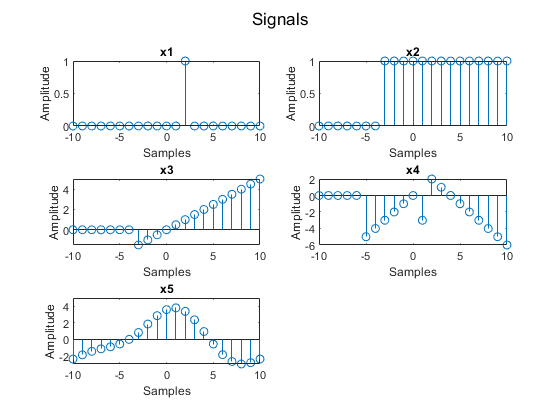

figure; sgtitle('Signals');
subplot(3,2,1); stem(n, x1); title('x1');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,2); stem(n, x2); title('x2');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,3); stem(n, x3); title('x3');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,4); stem(n, x4); title('x4');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,5); stem(n, x5); title('x5');
xlabel('Samples'); ylabel('Amplitude');

**Question 2**: In this question, we will build some basic systems in the form of functions (some which we will likely use again). Design the functions to accept input signals of arbitrary length and value. Function parameters are constrained as noted below. Input and output signals lengths should be equal. Assume all values outside of the range of the input signal are zero:

- Delay (or advance) system, $y=\textrm{delay}\left(x,M\right)$: $y[n] = x[n - M]$

- Causal running average system, $y={\textrm{running}}_- \textrm{avg}\left(x,M\right)$: $ y[n] = 1/M \sum_{m=0}^{M-1} x[n - m]$ where M is positive

- Anti-causal running average system, $y={\textrm{running}}_- \textrm{avga}\left(x,M\right)$: $y[n] = 1/M \sum_{m=1}^{M} x[n + m]$ where M is positive

- An accumulating energy system, , $y={\textrm{accum}}_- \textrm{energy}\left(x\right)$: $y[n] = \sum_{m=-\infty}^{n} |x[n]|^2$ 

- Reverberation system, $y=\textrm{reverb}\left(x,M,A\right)$: $ y[n] = A y[n - M] + x[n]$ where M is positive

%%% SETUP - DO NOT EDIT

% No setup

%%% ANSWER

% Fill in the corresponding functions found in this folder

%%% WRAPUP - DO NOT EDIT 

n = -5:20;
x_test = 2.*(n>=0).*(n<=2);

y1s = delay(x_test,2);
y2s = running_avg(x_test,4);
y3s = running_avga(x_test,4);
y4s = accum_energy(x_test);
y5s = reverb(x_test,4,0.5);

disp('Question 2 Figures')

Question 2 Figures


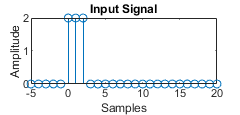

figure; 
set(gcf, 'Units', 'Inches', 'Position',[0 0 2.5 1.2])
stem(n, x_test); title('Input Signal')
xlabel('Samples'); ylabel('Amplitude');

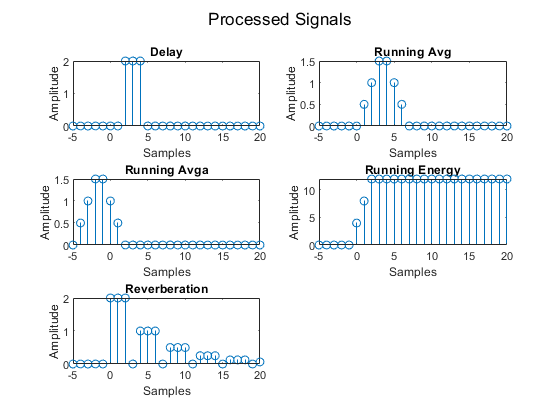


figure;  sgtitle('Processed Signals');
subplot(3,2,1); stem(n, y1s); title('Delay');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,2); stem(n, y2s); title('Running Avg');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,3); stem(n, y3s); title('Running Avga');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,4); stem(n, y4s); title('Running Energy');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,5); stem(n, y5s); title('Reverberation');
xlabel('Samples'); ylabel('Amplitude');

**Final Instructions**: It is very important you follow these instructions exactly. It will make grading easier, quicker, and more accurate:

- Do not change the name of this file nor the accompanying functions.

- When complete, select all six files (this MATLAB Live Script and the five MATLAB Script functions) and zip them into a folder named "code1_UFID" where UFID is your eight digit UFID number. Ensure the files are zipped directly. Do not put them in a folder then zip that folder.  

- Submit the resulting zipped folder to canvas along with any additional files from previous sections of this homework. 